%% LQR 1
clc; clear all; close all;
A = [0 0 1 0; 
     0 0 0 1; 
     0 149.3 -0.0104 0; 
     0 261.6 -0.0103 0];
B = [0 0 49.73 49.15]'
C = [1 0 0 0];
D = 0;

Q = diag([10 1 1 1])

Q =     10     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


R = 0.01;

K = lqr(A,B,Q,R)

K =   -31.6228  320.3636  -16.5133   31.3404


Kr = inv(-(C-D*K)*(A-B*K)^-1*B+D)

Kr = -31.6228


%Cerramos el Lazo
ACL = A-B*K;
BCL = B*Kr;
CCL = C-D*K;
DCL = D*Kr;

GLC = ss(ACL,BCL,CCL,DCL)

GLC =
 
  A = 
               x1          x2          x3          x4
   x1           0           0           1           0
   x2           0           0           0           1
   x3        1573  -1.578e+04       821.2       -1559
   x4        1554  -1.548e+04       811.6       -1540
 
  B = 
          u1
   x1      0
   x2      0
   x3  -1573
   x4  -1554
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


pole(GLC)

ans = 1.0e+02 *

  -6.9949 + 0.0000i
  -0.0827 + 0.0360i
  -0.0827 - 0.0360i
  -0.0315 + 0.0000i


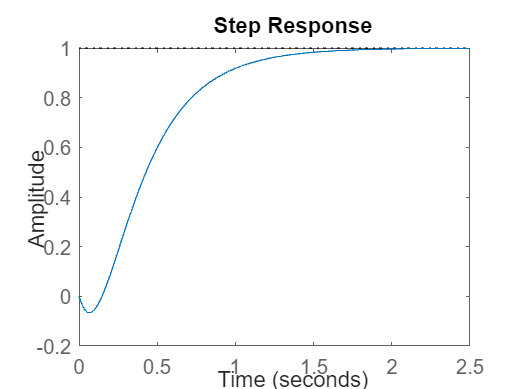

step(GLC)